# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with:

Run the script to create the layers in the workspace variable `layers`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 15-Jul-2021 17:40:10

## Create the Array of Layers

layers = [
    imageInputLayer([227 227 3],"Name","imageinput")
    convolution2dLayer([5 5],3,"Name","conv1","Padding","same")
    batchNormalizationLayer("Name","batchnorm1")
    reluLayer("Name","relu1")
    maxPooling2dLayer([5 5],"Name","maxpool1","Padding","same")
    convolution2dLayer([5 5],3,"Name","conv2","Padding","same")
    batchNormalizationLayer("Name","batchnorm2")
    reluLayer("Name","relu2")
    maxPooling2dLayer([5 5],"Name","maxpool2","Padding","same")
    fullyConnectedLayer(27,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

## Plot the Layers

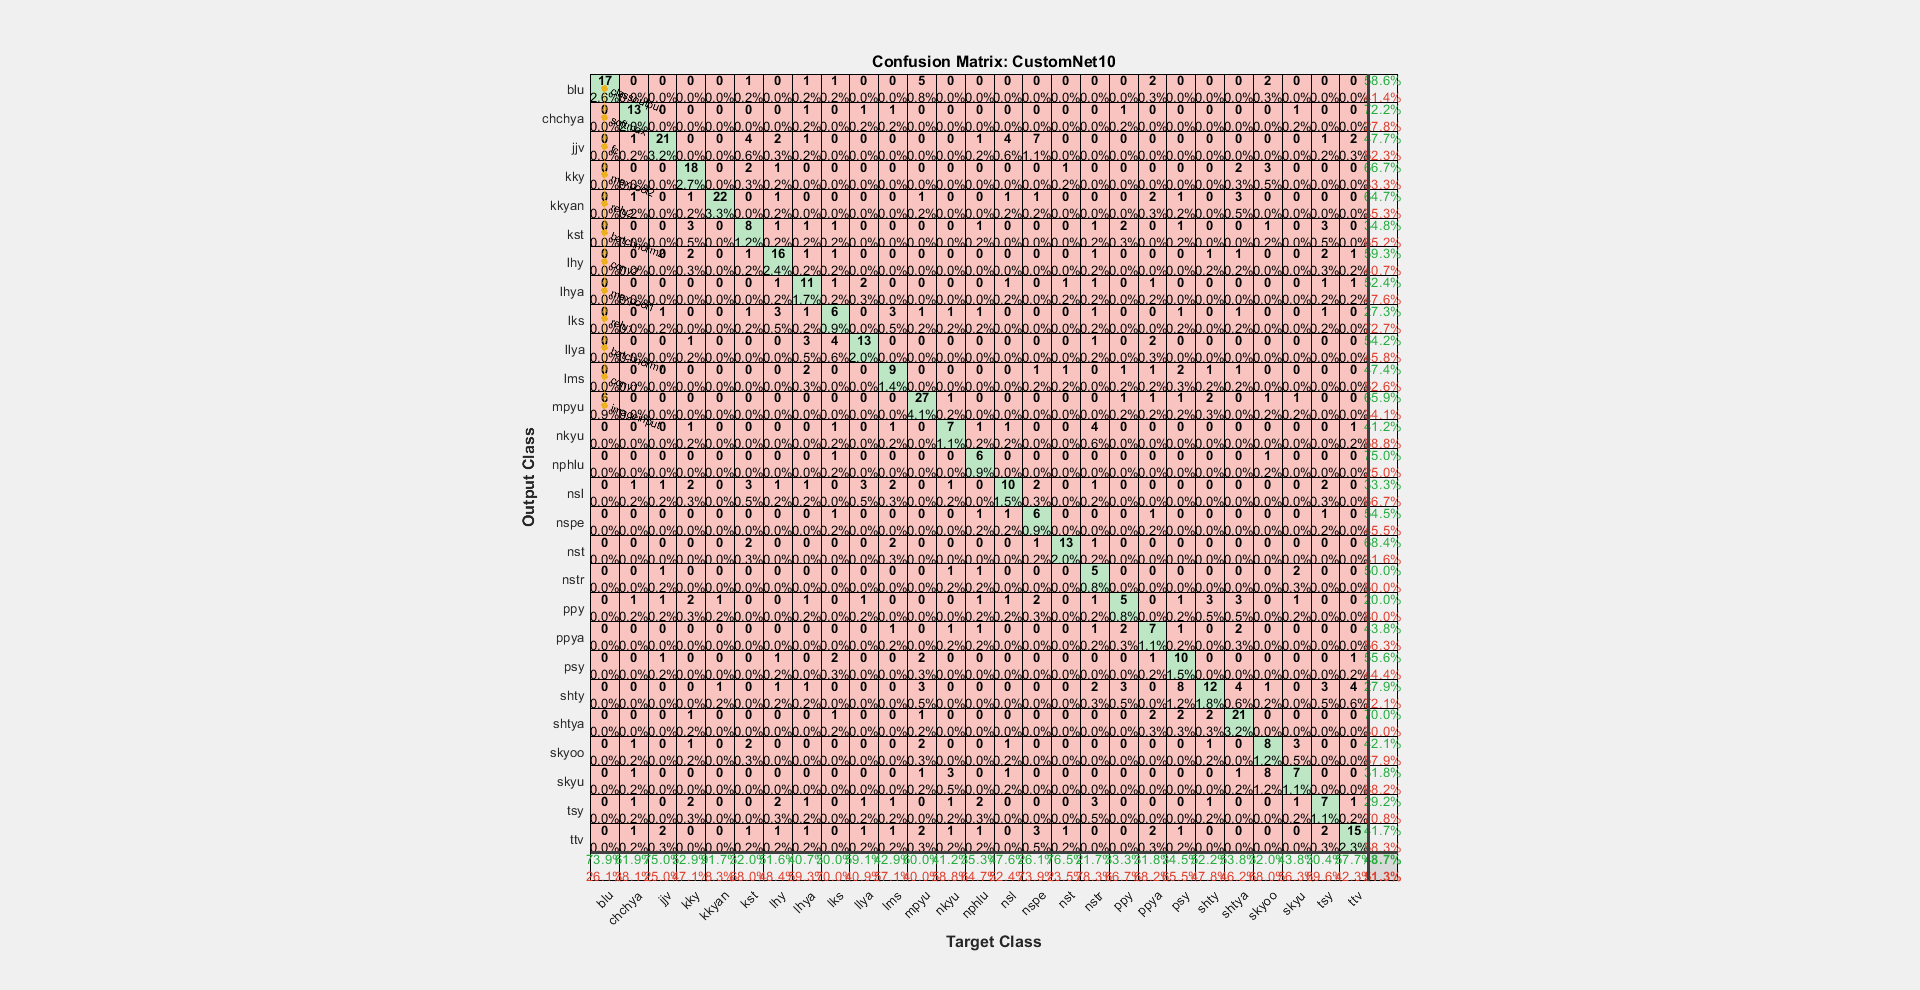

plot(layerGraph(layers));

datapath='C:\Users\HP\Pictures\ResizeMarathi';

% Image Datastore
imds=imageDatastore(datapath, ...
'IncludeSubfolders',true, ...
'LabelSource','foldernames');

% Determine the split up
total_split=countEachLabel(imds)

total_split = 27×2 table
    Label     Count
    ______    _____

    blu        116 
    chchya     105 
    jjv        141 
    kky        170 
    kkyan      122 
    kst        125 
    lhy        153 
    lhya       136 
    lks        101 
    llya       111 
    lms        105 
    mpyu       224 
    nkyu        84 
    nphlu       85 
    nsl        106 
    nspe       113 


## Training, Testing and Validation

Let's split the dataset into training, validation and testing. At first, we are splitting the dataset into groups of 80% (training & validation) and 20% (testing). Make sure to split equal quantity of each class.

% Split the Training and Testing Dataset
train_percent=0.80;

[imdsTrain,imdsTest]=splitEachLabel(imds,train_percent,'randomize');

% Split the Training and Validation
valid_percent=0.2;

[imdsValid,imdsTrain]=splitEachLabel(imdsTrain,valid_percent,'randomize');

train_split=countEachLabel(imdsTrain);

**Preprocess Training and Validation Dataset**

Alternatively, we could utilize the recommended [augumentedImageDatastore](https://www.mathworks.com/help/deeplearning/ref/augmentedimagedatastore.html) for faster resizing and [transform](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.transform.html)/[combine](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.combine.html) to alter the dataset.

imdsTrain.ReadFcn=@(filename)preprocess_marathi_images(filename,[layers(1).InputSize(1), layers(1).InputSize(2)]);
imdsValid.ReadFcn=@(filename)preprocess_marathi_images(filename,[layers(1).InputSize(1), layers(1).InputSize(2)]);

## Train the network

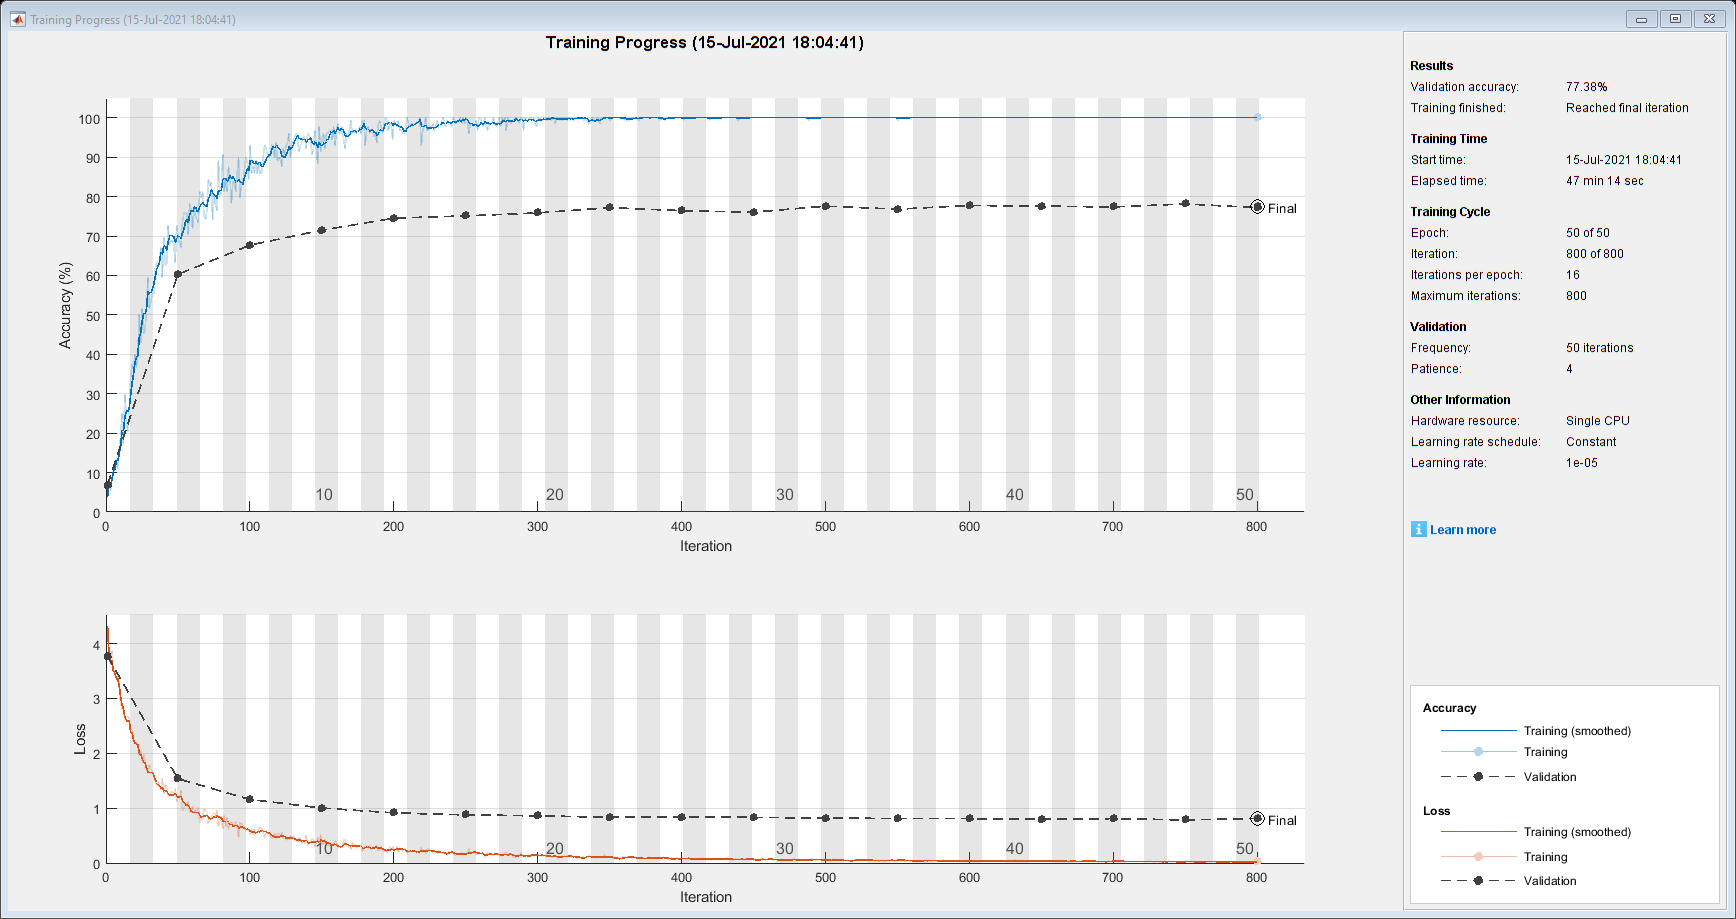

options=trainingOptions('adam', ...
    'MiniBatchSize',128, ...
    'MaxEpochs',50, ...
    'Shuffle','every-epoch', ...
    'InitialLearnRate',1e-5, ...
    'ValidationData',imdsValid, ...
    'ValidationFrequency',50,'ValidationPatience',4, ...
    'Verbose',false, ...
    'Plots','training-progress');
% Train the network
netTransfer=trainNetwork(imdsTrain,layers,options);

## Testing

Now, let's study the performance of the network on the test set.

% Preprocess the test cases similar to the training
imdsTest.ReadFcn=@(filename)preprocess_marathi_images(filename,[layers(1).InputSize(1), layers(1).InputSize(2)]);

% Predict Test Labels using Classify command
[predicted_labels,posterior]=classify(netTransfer,imdsTest);

**Performance **

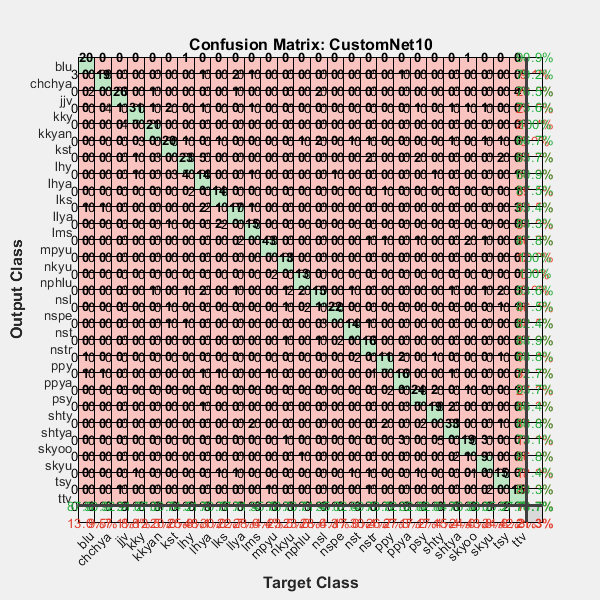

% Actual Labels
actual_labels=imdsTest.Labels;

% Confusion Matrix
figure;
plotconfusion(actual_labels,predicted_labels)
title('Confusion Matrix: CustomNet10');

figure

ROC would assist the us in choosing his/her operating point in terms of false positive and detection rate.

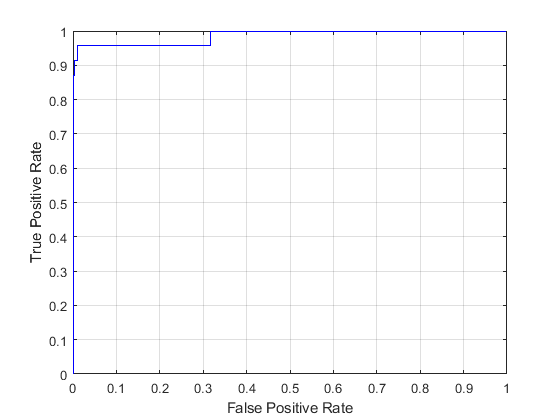

test_labels=double(nominal(imdsTest.Labels));

% ROC Curve - Our target class is the first class in this scenario.

[fp_rate,tp_rate,T,AUC]=perfcurve(test_labels,posterior(:,1),1);
%[fp_rate,tp_rate,T,AUC,OPTROCPT] = perfcurve(test_labels,scores,posclass)
figure;
plot(fp_rate,tp_rate,'b-');hold on;
grid on;
xlabel('False Positive Rate');
%ylabel('Detection Rate');
ylabel('True Positive Rate');

You can use `confusionchart` to plot a the confusion matrix as a confusion matrix chart.

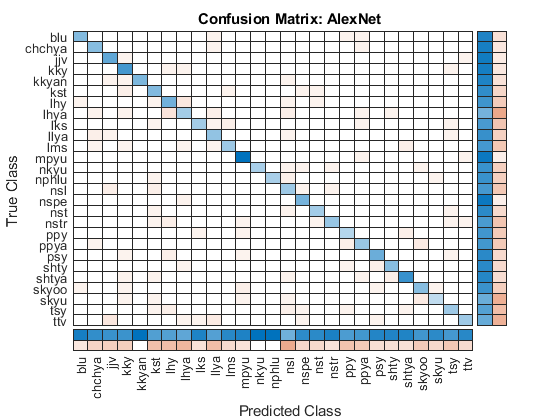

figure
%cm = confusionchart(m,order);
cm1 = confusionchart(actual_labels,predicted_labels, ...
    'Title','Confusion Matrix: AlexNet', ...
    'RowSummary','row-normalized', ...
    'ColumnSummary','column-normalized');

figure
cm = confusionchart(actual_labels,predicted_labels, ...
    'Title','Classification of Marathi Handwritten Compound Character using SVM', ...
    'RowSummary','row-normalized', ...
    'ColumnSummary','column-normalized');

Normalized

cm.NormalizedValues

ans =     20     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     1     1     0     0     0     0     0     0     0
     0    19     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0
     0     0    26     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     0     0     0    31     0     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0
     0     0     1     1    21     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     2     0    20     0     0     0     0     1     0     0     0     0     1     1     0     0     0     0     0     0     0     0     0     0
     1     0    

To sort the confusion matrix according to the positive predictive value, normalize the cell values across each column by setting the `Normalization` property to `'column-normalized'` and then use `sortClasses`. After sorting, reset the `Normalization` property back to `'absolute'` to display the total number of observations in each cell.

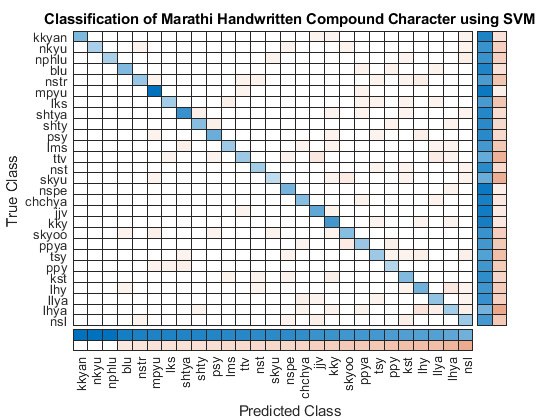

cm.Normalization = 'column-normalized';
sortClasses(cm,'descending-diagonal')
cm.Normalization = 'absolute'; 

` Prcision and Recall Values`


 cm = confusionmat(actual_labels,predicted_labels);
    cm = cm';
    precision = diag(cm)./sum(cm,2);
    overall_precision = mean(precision)

overall_precision = 0.7984

    recall= diag(cm)./sum(cm,1)';
    overall_recall = mean(recall)

overall_recall = 0.7750